# Analisi Algoritmo di Bisezione 

In questa documentazione si mostreranno i casi di test relativi all'algoritmo di bisezione.

# Test di accuratezza

Il  test di accuratezza determina quanto la soluzione approssimata trovata attraverso il metodo di bisezione si avvicina alla soluzione dell'algoritmo fzero(). Quest'ultimo è il migliore algoritmo utilizzato per ffff lo zero in Matlab. Ai fini del calcolo dell' accuratezza è stata implementata la funzione CalcoloAccuratezza() . Essa calcola l'errore relativo tra le soluzioni restituite dai due algoritmi al medesimo problema. Una breve documentazione e l'implementazione della funzione è disponibile: 

doc CalcoloAccuratezza

## **Esempio**

Calcolare lo zero  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ al variare della tolleranza TOL inserita dall'utente supponendo NMAX di default.

`Command line Matlab`

f = @(x)(2-exp(-x)-sqrt(x));
x0 = [0 4];

CalcoloAccuratezza(f,x0,1e-10)
CalcoloAccuratezza(f,x0,1e-11)
CalcoloAccuratezza(f,x0,1e-12)
CalcoloAccuratezza(f,x0,1e-13)
CalcoloAccuratezza(f,x0,1e-14)
CalcoloAccuratezza(f,x0,1e-15)
CalcoloAccuratezza(f,x0,eps)

`Esecuzione da interfaccia grafica`

MainGUI();

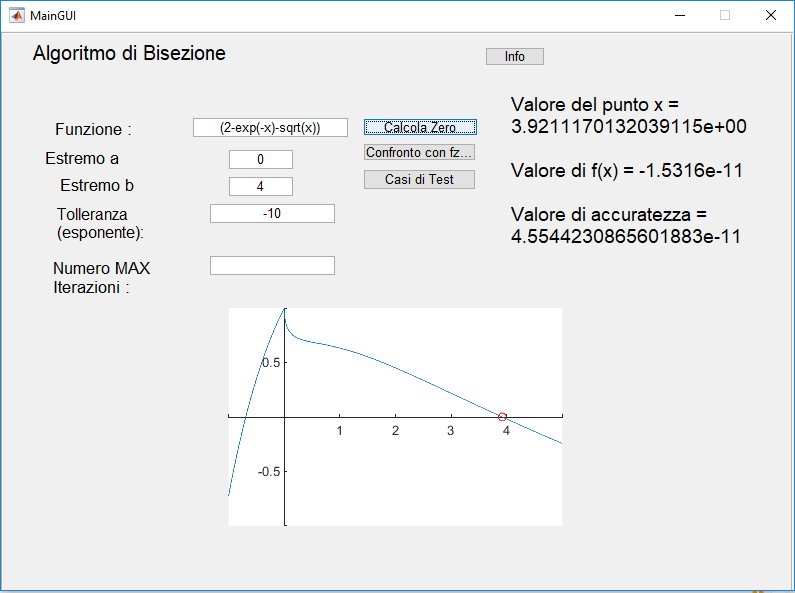

# Valutazione Performance

Si è implementata una funzione che crea un grafico di confronto tra i due algoritmi sopra citati. Si è calcolata la performance confrontando il numero di iterazioni necessarie all'algoritmo di Bisezione con quelle necessarie alla funzione fzero() considerata la tolleranza richiesta. 

## **Esempio**

Calcola la performance dell'algoritmo di bisezione quando è in input f=  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ al variare della tolleranza TOL inserita dall'utente supponendo NMAX di default.L La funzione restituirà un grafico di confronto tra i due approcci.

`Command line Matlab`

f = @(x) (2-exp(-x)-sqrt(x));%funzione handle
xo = [0 4];
TOL=[10.^-1 10.^-2 10.^-3  10.^-4 10.^-5 10.^-6 10.^-7 10.^-8 10.^-9 10.^-10 10.^-12 10.^-13 10.^-14 eps];
Valuta_Performance(f,x0,TOL);

`Esecuzione da interfaccia grafica`

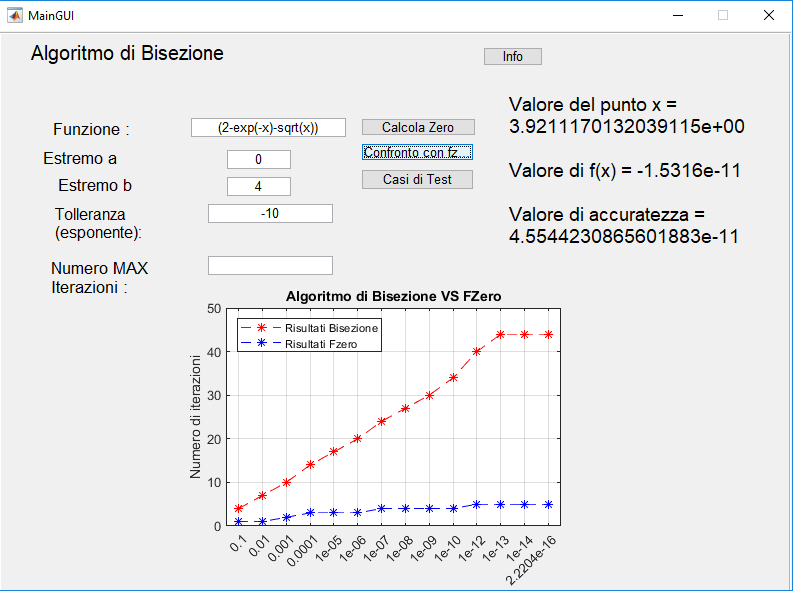

Come si nota dal grafico il numero di iterazioni richieste dalla funzione fzero() è minore rispetto a quelle della funzione algoritmo_di_bisezione() per ogni valore di TOL. Si può osservare che la differenza tra i due approcci è tanto più marcata quanto più si cerca una risoluzione migliore diminuendo la tolleranza.

# Test di robustezza

Per valutare la robustezza dell'algoritmo è stata implementata una test suite. I casi di test sono stati scelti a partire dalle condizioni di errore o warning che possono avere luogo. Ogni caso di test lo descriveremo brevemente a partire dai parametri di input e dalla funzionalità che  viene testata. Il numero di casi di test è: 15 ,implementati in una classe definita dal matlab *matlab.unittest.TestCase*. In tal modo si è automatizzato il processo di esecuzione dei test. Le istruzioni per eseguire i test sono le seguenti:

result1 = runtests('exec_tests.m');
table(result1)

Il sistema esegue in automatico i test, riportando in tabella i test eseguiti con successo e quelli senza successo.

Per ogni insieme di input della funzione vengono effettuati tutti i test presenti nella test suite. La funzione che permette il trasferimento dei parametri della funzione a exec_tests.m è Get_Values(). 

function [f,x0,TOL,NMAX] = Get_Values()
f =  @(x) 2-exp(-x)-sqrt(x);
x0 =[0 4];
TOL = 10^-15;
NMAX = 999;
end

Di seguito seguono i casi di test più rilevanti che sono stati effettuati:

## Test case 1 

 Verifica l'errore nel caso in cui il primo estremo o il secondo estremo dell'intervallo inserito non è un numero.

###     Input

- f: 

- x0:

- TOL:

## Test case 2

 Verifica l'errore nel caso in cui entrambi gli  estremi dell'intervallo x0  siano vuoti.

### Input

- f: 

- x0:

- TOL:

## Test case 3

 Verifica l'errore nel caso in cui entrambi i valori dell'intervallo x0 siano uguali.

### Input

- f: 

- x0:

- TOL

function TestCase4(testCase)
%verifica l'errore nel caso in cui entrambi i valori
%dell'intervallo sono uguali.
[f,x0] = Get_Values();
verifyNotEqual(testCase,x0(1),x0(2));

end

## Test case 6

Verifica l'errore nel caso in cui non è soddisfatto il teorema degli zeri.

### Input

- f: 

- x0:

- TOL

function TestCase6(testCase)
[f,x0] = Get_Values();
if(f(x0(1))*f(x0(2)) > 0)
    verifyReturnsTrue(testCase,@false);
else
    verifyReturnsTrue(testCase,@true);
end
end
end



## Test case 8

Verifica se l'accuratezza è adeguata  a partire da una determinata tolleranza TOL.

- f: 

- x0:

- TOL

function TestCase8(testCase)
%verifica se l'accuratezza è adeguata con TOL inserita.
[f,x0,TOL] = Get_Values();
[x, uscita, graf]= algoritmo_di_bisezione(f,x0,TOL);
actSolution=x;
options = optimset('TolX',TOL);
expSolution=fzero(f,x0,options);
abs_error = abs(actSolution - expSolution)/abs(expSolution);
verifyLessThan(testCase,abs_error,eps*max(actSolution,expSolution),'Risultato poco accurato');


## Test case 12

Verifica se il valore di NMAX  non è numerico, scalare,infinito oppure NaN.

- f: 

- x0:

- TOL

    function TestCase12(testCase)
        %Caso 12 : Verifica il valore di NMAX
        [~,~,~,NMAX] = Get_Value();
        if(~isscalar(NMAX) || ~isnumeric(NMAX) || isinf(NMAX) || isnan(NMAX))
            verifyReturnsTrue(testCase,@false)
        else
            verifyReturnsTrue(testCase,@true)
        end
    end

## Caso di test 14                                                                                                                      

Verifica se il valore di NMAX è minore o uguale a 2.

- f: 

- x0:

- TOL

    function TestCase14(testCase)
        %Caso 14 : Verifica se il valore di NMAX è minore o uguale a 2
        [~,~,~,NMAX] = Get_Values();
        if(NMAX<=2)
            verifyReturnsTrue(testCase,@false)
        else
            verifyReturnsTrue(testCase,@true)
        end
    end

## Caso di test 15                                                                                                                      

 Verifica se il valore delle iterazioni di uscita è maggiore o uguale a 1000.

- f: 

- x0:

- TOL

 function TestCase15(testCase)
               %Caso 15 : Verifica se il valore delle iterazioni di uscita
               %è maggiore o uguale a 1000.
                [f,x0,TOL,NMAX] = Get_Values();
                   [x, uscita,~ ]= algoritmo_di_bisezione(f,x0,TOL,NMAX);
                if(uscita.numiter>=1000)
                    warning('Il numero di iterazioni inserito è molto alto, l''esecuzione potrebbe essere più lenta'); 
                    verifyReturnsTrue(testCase,@false)
                else
                    verifyReturnsTrue(testCase,@true)
                end
 end

##    Esecuzione dei test

A partire da alcuni insiemi di input viene restituita la tabella di esecuzioni di test.

 Richiama_Parametri(f,x0,TOL,NMAX); %parametri di input
 result1 = runtests('exec_tests.m');
 table(result1);

  Richiama_Parametri(f,x0,TOL,NMAX); %parametri di input
 result1 = runtests('exec_tests.m');
 table(result1);
 

 Richiama_Parametri(f,x0,TOL,NMAX); %parametri di input
 result1 = runtests('exec_tests.m');
 table(result1);
 
 

 Richiama_Parametri(f,x0,TOL,NMAX); %parametri di input
 result1 = runtests('exec_tests.m');
 table(result1);
 

 Richiama_Parametri(f,x0,TOL,NMAX); %parametri di input
 result1 = runtests('exec_tests.m');
 table(result1);
 


## Riferimenti                                                                                                                  

[1] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[2] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autori                                                                                                                          

** Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936**